# Integrated Script for Simulation of Semi-Structured Intelligent Bin Picking With Universal Robots UR5e 

### Overview

This script does the integration of **Motion Planning** and **Perception** modules to create a full bin-picking workflow. 

Before running this script it is recommended to go through the Perception script `DetectionAndPoseEstimationforCuboidSim.mlx` and Motion Planning MEX generation script `DetectionAndPoseEstimationforCuboidSim.mlx`, if not already. 

#### Load Rigid Body Tree Model

Load rigid body tree model for Universal Robot UR5e robot manipulator with an end-effector body. The function `exampleHelperAddGripper` is used to add the additional end-effector body (the Robotiq Epick suction gripper) as a collision objects for precise motion planning.

rbt = importrobot('universalUR5e.urdf','DataFormat','row');
ur5e = exampleHelperAddGripper(rbt);

#### Connect to ROS Host

Provide parameters of the host machine with ROS. (In this case, provide the parameters of your virtual machine)

ROSDeviceAddress = '192.168.132.128'; % IP address
username = 'user'; % User name
password = 'password'; % Password corresponds to user name

ROSFolder = '/opt/ros/noetic'; % ROS installation folder
WorkSpaceFolder = '~/ur_ws'; % UR ROS driver installation workspace folder location

device = rosdevice(ROSDeviceAddress,username,password);
device.ROSFolder = ROSFolder;

#### Generate Launch Script and Transfer it to ROS Host Computer

This section creates and launches the script automatically in the ROS host machine to launch the required ROS nodes for the UR5e robot.

generateAndTransferLaunchScriptForUR5eSimGazebo(device,WorkSpaceFolder);

if ~isCoreRunning(device)
    w = strsplit(system(device,'who'));
    displayNum = cell2mat(w(2));

    system(device,['export SVGA_VGPU10=0; ' ...
        'export DISPLAY=' displayNum '.0; ' ...
        './launchURBinPicking.sh &']);
    pause(10);
end
gzinit(ROSDeviceAddress,14581);
rosshutdown;

Shutting down global node /matlab_global_node_63893 with NodeURI http://192.168.132.1:64173/ and MasterURI http://192.168.132.128:11311.


rosinit(ROSDeviceAddress);

Initializing global node /matlab_global_node_28236 with NodeURI http://192.168.132.1:64364/ and MasterURI http://192.168.132.128:11311.


#### Create an instance of the `universalrobot` class  

The `universalrobot` object has several useful properties. The `RigidBodyTree` property contains the rigid body tree model, which is being used internally for trajectory generation and motion planning. 

pause(20);
% Create an instance to communicate with the simulated UR5e cobot
ur = universalrobot(ROSDeviceAddress,'RigidBodyTree',ur5e);

Using user-defined rigid body tree model.


#### Move the robot to the home position

`homePosition `parameter is defined in the `initializeParametersForBinPickingSimulation.m` script. You can find this script inside the **Initialize** folder of the project.

% Send To home position
sendJointConfigurationAndWait(ur,homePosition,'EndTime',2);
pause(2);

## Spawn the objects

% call ROS service for pause the Gazebo world
physicsClientPause = rossvcclient('gazebo/pause_physics');
call(physicsClientPause,'Timeout',3);

% Set states for table, bin and stand
gzmodel('set','bin_picking_stand','Position',[0 0 0.001],'Orientation',eul2quat([0,0,0]))

STATUS:  Succeed


MESSAGE:  Parameter set successfully.




pause(0.5);
gzmodel('set','pvc_tray','Position',[0.48 0 0.55],'Orientation',eul2quat([1.57 0 0]),"SelfCollide","off","IsStatic","on")

STATUS:  Succeed


MESSAGE:  Parameter set successfully.




pause(0.5);
gzlink('set','table_solid','link','Position',[0.17 0.68 0.4],'Orientation',eul2quat([0,0,0]));

STATUS:  Succeed


MESSAGE:  Parameter set successfully.





% call ROS service for un-pause the Gazebo world
physicsClientUnpause = rossvcclient('gazebo/unpause_physics');
call(physicsClientUnpause,'Timeout',3);

% create mesh
px1 = -0.20:0.12:0.24;
py1 = -0.12:0.11:0.12;

py1 = py1(randperm(length(py1)))+0.48;
px1 = px1(randperm(length(px1)));

temp = cell(length(px1),length(py1));

for i = 1:length(px1)
    for j = 1:length(py1)
        temp(i,j) = {[px1(i), py1(j)]};
    end
end

newPose = reshape(temp,[1,length(px1)*length(py1)]);

% get the list of the world models
modelList = gzmodel("list");

% list of the target objects (naming starts with part1, part2 etc.)
partList = modelList(contains(modelList,"part"));


ii=randperm(length(newPose));
b=newPose(ii);

% spawn the world
for i=1:length(partList)
    partGT = cell2mat(b(i));
    gzlink('set',partList(i),'link','Position',[partGT(2) partGT(1) 0.7],'Orientation',eul2quat([rand*pi*0.8,0,0]));
end

STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.




pause(3);

% semi-structure distribution constraint 
for i=1:length(partList)
    % Check if the part is not in the favourable orientation. Change the
    % orientation in this case
    partOrient = quat2eul(gzlink('get',partList(i),'link','Orientation'),"XYZ");
    if abs(partOrient(1)) > 0.01 || abs(partOrient(2)) > 0.01
        gzlink('set',partList(i),'link','Orientation',eul2quat([rand*pi*0.8,0,0]));
    end
end
pause(3);


## Perception 

This diagram shows the steps involve in the object pose estimation using YOLOv4 and PCA based algorithm. 

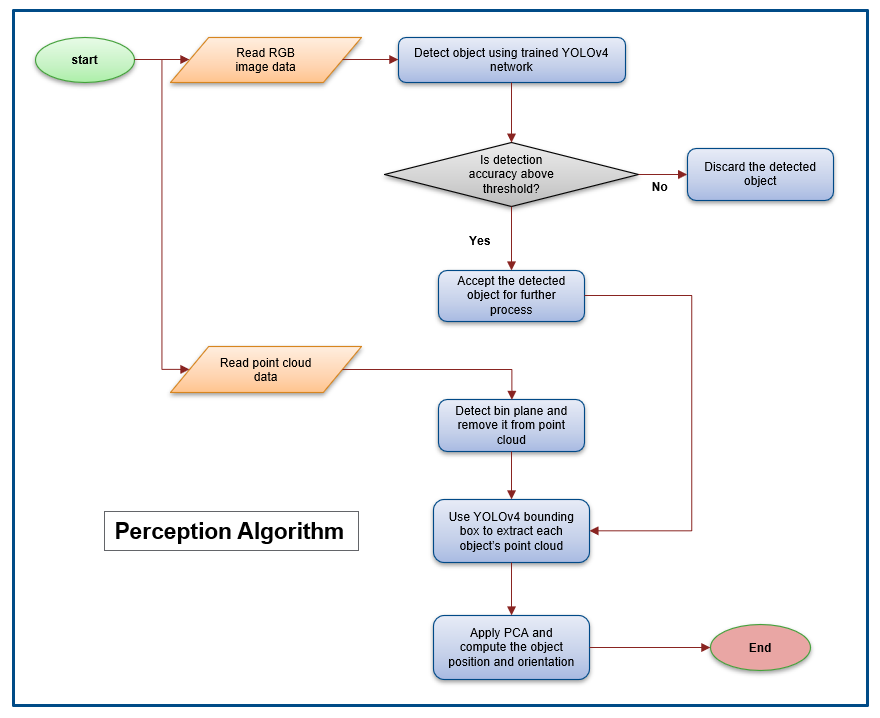

#### Read point cloud and RGB data from the camera sensor

This section creates one additional MATLAB ROS node to communicate with the ROS master to subscribe to the ROS topics for reading the raw RGB and point cloud data.

- The "/camera/color/image_raw" ROS topic is used to read the RGB data.

- The "/camera/depth/color/points" ROS topic is used to read the point cloud data.

Note that "PreserveStructureOnRead" argument is set "true" while reading the data from both the subscriber to preserve the original data size (640 x 280).

rgbImgSub = rossubscriber('/camera/color/image_raw','DataFormat','struct');
subi = receive(rgbImgSub);
rgbImage = rosReadImage(subi,"PreserveStructureOnRead",true);

pointCloudSub = rossubscriber('/camera/depth/color/points','DataFormat','struct');
sub = receive(pointCloudSub);
ptCloud = rosReadXYZ(sub,"PreserveStructureOnRead",true);
ptCloud = pointCloud(ptCloud);

#### Detect objects using trained YOLO network

Set `showPartialOutputs `flag to "true" if you want to visualize the output from the YOLO object detector.

showPartialOutputs = true;

Load the pre-trained YOLO object detector. The training script is provided in the **Perception** folder of this project. Run the below-given command if you want to open the training script.

pretrained = load('trainedYOLOv4DetectorSimGazebo_cuboid.mat')

pretrained = struct with fields:
       detector: [1×1 yolov4ObjectDetector]
    elapsedTime: 91.4040
           info: [1×1 struct]


trainedYoloNet = pretrained.detector; %YOLOv4 network

Run the object detector function to detect the object from the input image taken from the IntelRealSense D415 Gazebo camera sensor. The `detectObjectsYoloNet` function is created to perform object detection using the pretrained YOLOv4 model.

Refer to the** Perception** folder to check `detectObjectsYoloNet` function definition.

[bboxes,scores,labels] = detectObjectsYoloNet(trainedYoloNet,rgbImage);

Visualize the output from YOLOv4 detector with` rgbImage` data.

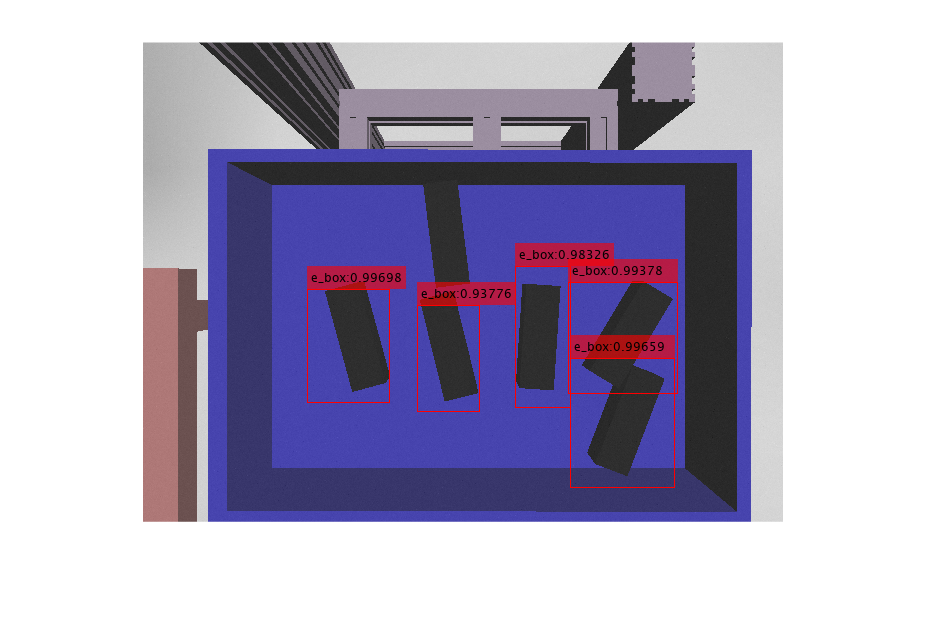

if(showPartialOutputs)
    % visualize the detected object bounding box
    annotatedImage = insertObjectAnnotation(im2uint8(rgbImage), 'Rectangle',...
        bboxes, string(labels)+":"+string(scores),'Color','r');
    figure, imshow(annotatedImage);
end

Choose objects which have a detection confidence score higher than yoyloScoreTh for further processing

validIdx = scores > yoyloScoreTh;
bboxes = bboxes(validIdx, :);
scores = scores(validIdx);
labels = labels(validIdx);
numObjects = size(bboxes,1);

#### Detect the plane and remove the plane from the point cloud

In this section, `pcfitplane` is used to find the indices of the points which refers to the plane. Then further this result is used to pre-process the point cloud by removing the plane from the original point cloud.

% Find plane and non-plane indices of the points from the point cloud
[param, planeIdx, nonPlaneIdx] = pcfitplane(ptCloud, PlanrThickness, normalvector, maxPlaneTilt);

% Create new point cloud by selecting only plane indices from original
% point cloud
plane = select(ptCloud, planeIdx);

% Create new point cloud by selecting non-plane indices from original
% point cloud
nonPlane = select(ptCloud, nonPlaneIdx);

if(showPartialOutputs)
    figure,pcshow(plane,'ViewPlane','XY');axis on;
end

% Create non-plane mask of the same size as raw input image
[m,n,~] = size(rgbImage);
nonPlaneMask = zeros(m,n);
nonPlaneMask =nonPlaneMask(:);
nonPlaneMask(nonPlaneIdx)= 1;

#### Estimate object poses

Here `findObjectPoses `function is used to compute the pose (Position + Orientation with respect to vertical Z axis) from the detected objects bounding box and pre-processed point cloud. This function uses [pca](https://in.mathworks.com/help/stats/pca.html) function which does Principle Component Analysis (PCA) to find the orientation of the detected object from its extracted point clouds. 

Note that pose is considered as [centerX centerY centerZ rotationZ] which is Position and Orientation with respect to vertical Z axis. 

Also note that the computed pose is with respect to the camera frame. 

% Compute the object pose from YOLO output
[xyz,theta,ptCloudVector,ptCloudParameterVector] = findObjectPoses(ptCloud,rgbImage, bboxes, gridDownsample, nonPlaneMask);

% Visualize computed PCA
if(showPartialOutputs)
    figure;
    for idx = 1: numObjects
        U = ptCloudParameterVector{idx}.UVW(:,1);
        V = ptCloudParameterVector{idx}.UVW(:,2);
        W = ptCloudParameterVector{idx}.UVW(:,3);
        centerOfObject = ptCloudParameterVector{idx}.centroid;
        nexttile;
        pcshow(ptCloudVector{idx},'ViewPlane','XY');
        hold on;
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(1), V(1), W(1), 'r');
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(2), V(2), W(2), 'g');
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(3), V(3), W(3), 'b');
        hold off;
    end
end

Compute object orientation with respect to robot coordinate system using the rotation matrix.

thetaNew = zeros(numObjects,1);
for idx = 1:numObjects
    U = ptCloudParameterVector{idx}.UVW(:,1);
    V = ptCloudParameterVector{idx}.UVW(:,2);
    W = ptCloudParameterVector{idx}.UVW(:,3);
    majorAxis = [U(1), V(1), W(1)];
    majorAxis = (rotationFromRobotToCam*majorAxis')';
    %This calculates the angle between the positive y axis ([ 0 1 0]) and the major axis of the object in an anti-clockwise direction
    thetaNew(idx) = atan2d(dot([0 0 1],cross([  0 1 0],majorAxis)),dot([ 0 1 0],majorAxis));
    if (thetaNew(idx)<0)
        thetaNew(idx) = 180 + thetaNew(idx);
    end
end

#### Create PartGT from the PCA output

Use parameter rotation matrix and camera translation to compute the compute final part ground truth `partGT `for motion planning.

partGT = zeros(numObjects,4);

for i=1:length(ptCloudParameterVector)
    partGT(i,1:3) = rotationFromRobotToCam*xyz(i,:)' + posDepthCam';
    partGT(i,4) = thetaNew(i);
end

## Motion planning

This section includes the computation of the feasible trajectories for the pick and place operation of each detected object from the bin. The generated MEX function `exampleHelperBinPickingRRTMotionPlannerSim_mex `is used here to compute the feasible waypoint using the `manipulatorRRT` algorithm. Then further [`contopptraj`](https://in.mathworks.com/help/robotics/ref/contopptraj.html?s_tid=doc_ta) is used to optimize the trajectory considering the maximum and minimum limit of acceleration and velocity. 

The parameters vellimits and accellimits are set in the` initializeParametersForBinPickingSimulation.m` script. You can find this script in the **Initialize **folder of this project.

Here is the description of the motion planning algorithm steps.

### **Part Selection Algorithm**

From the available parts to pick, the algorithm calculates the distance between the center of the part and the center of the bin. The part with the least distance from the bin center is selected for the next pick-place cycle. This logic is designed in such a way that its pick object based on picking complexity. Here light green color object in the below figure represents the selected object based on the algorithm as its center is closest to the bin center.

For more details on the part selection logic, see the `exampleHelperSelectPartForMEXPlannerSim.m` function which can be found inside the **Integration** folder. 

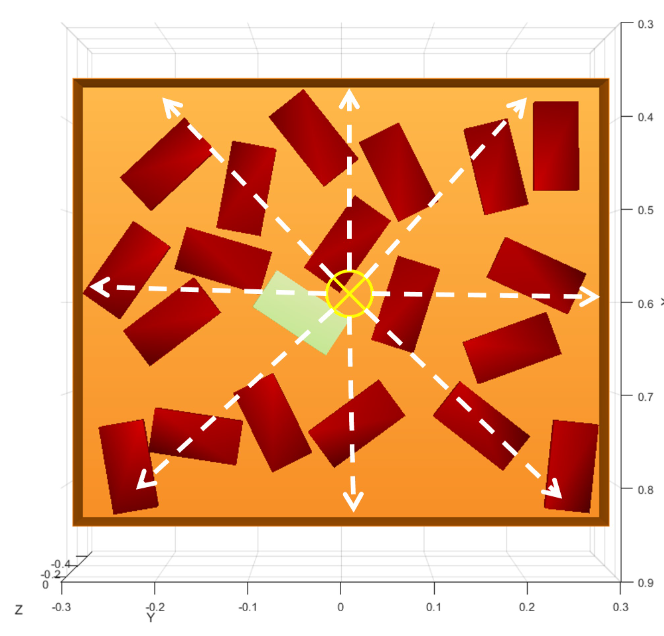

There are four aspects of motion planning as below.

#### **Approach:**

Approach trajectory is defined as traversing from the home position to the center of the part surface.

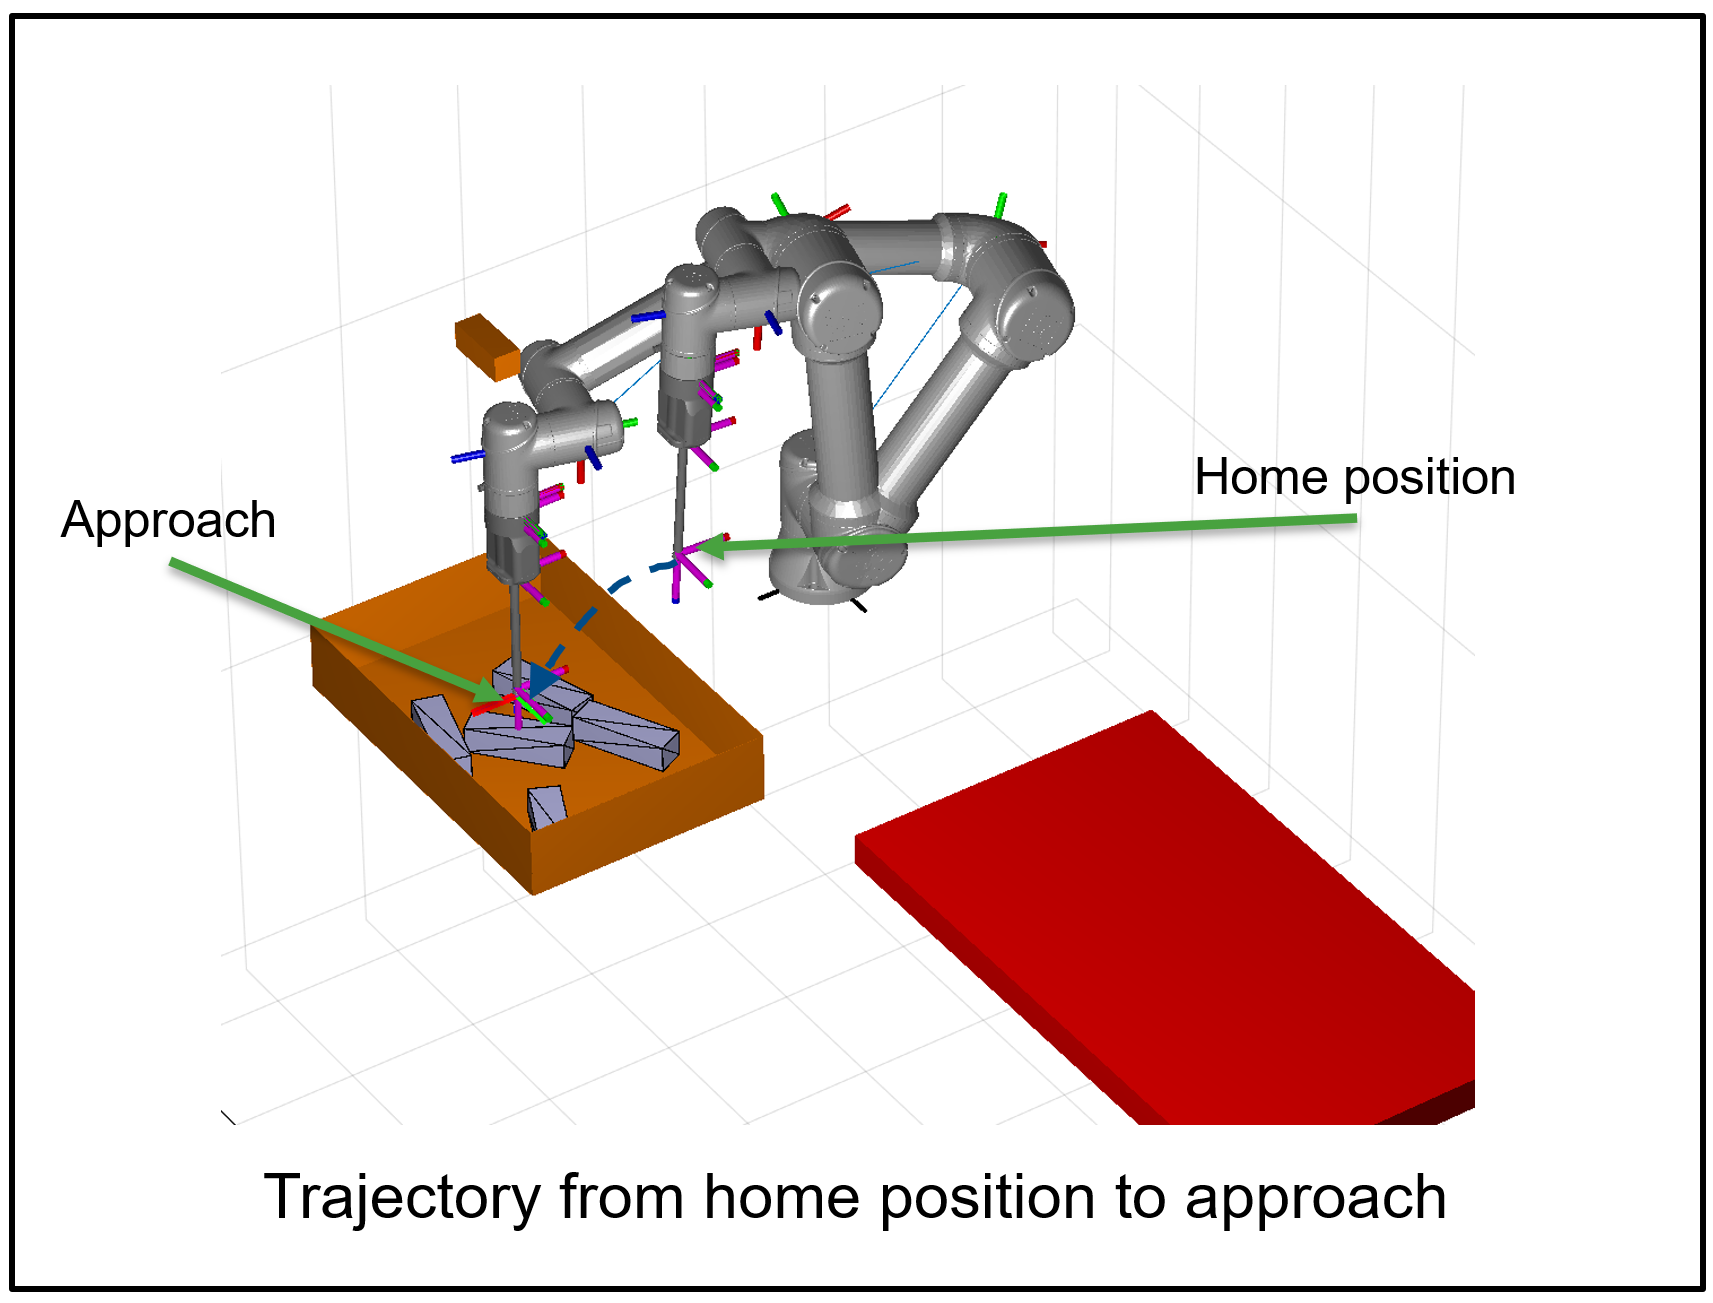

#### **Pick:**

Pick trajectory is defined as traversing from the center of the part surface to the intermediate home position.

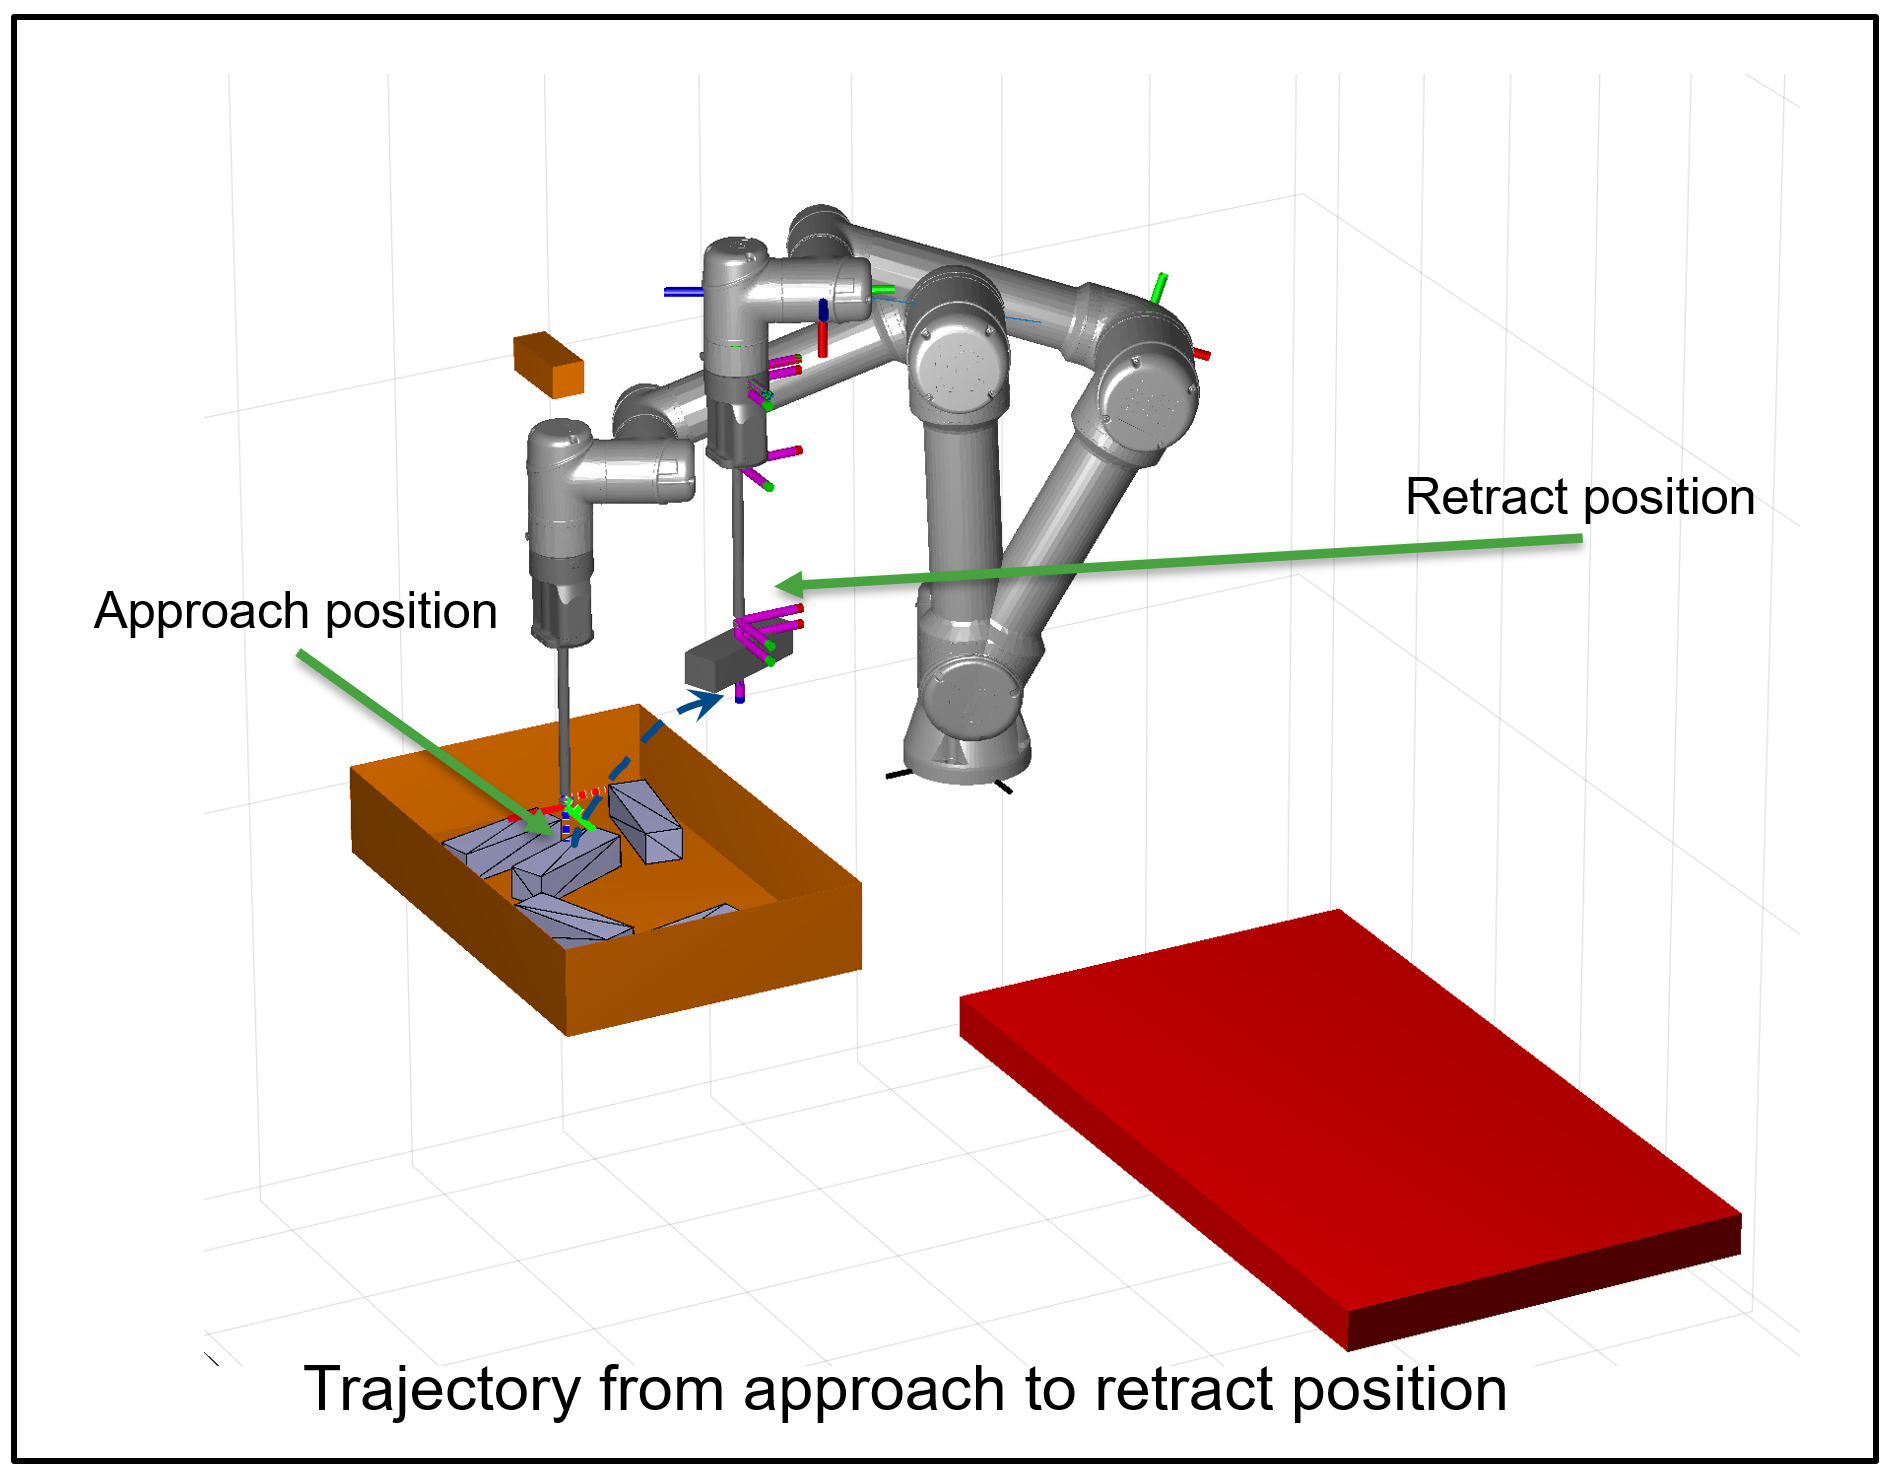

#### **Place:**

Place trajectory is defined as traversing from the intermediate home position to the desired destination.

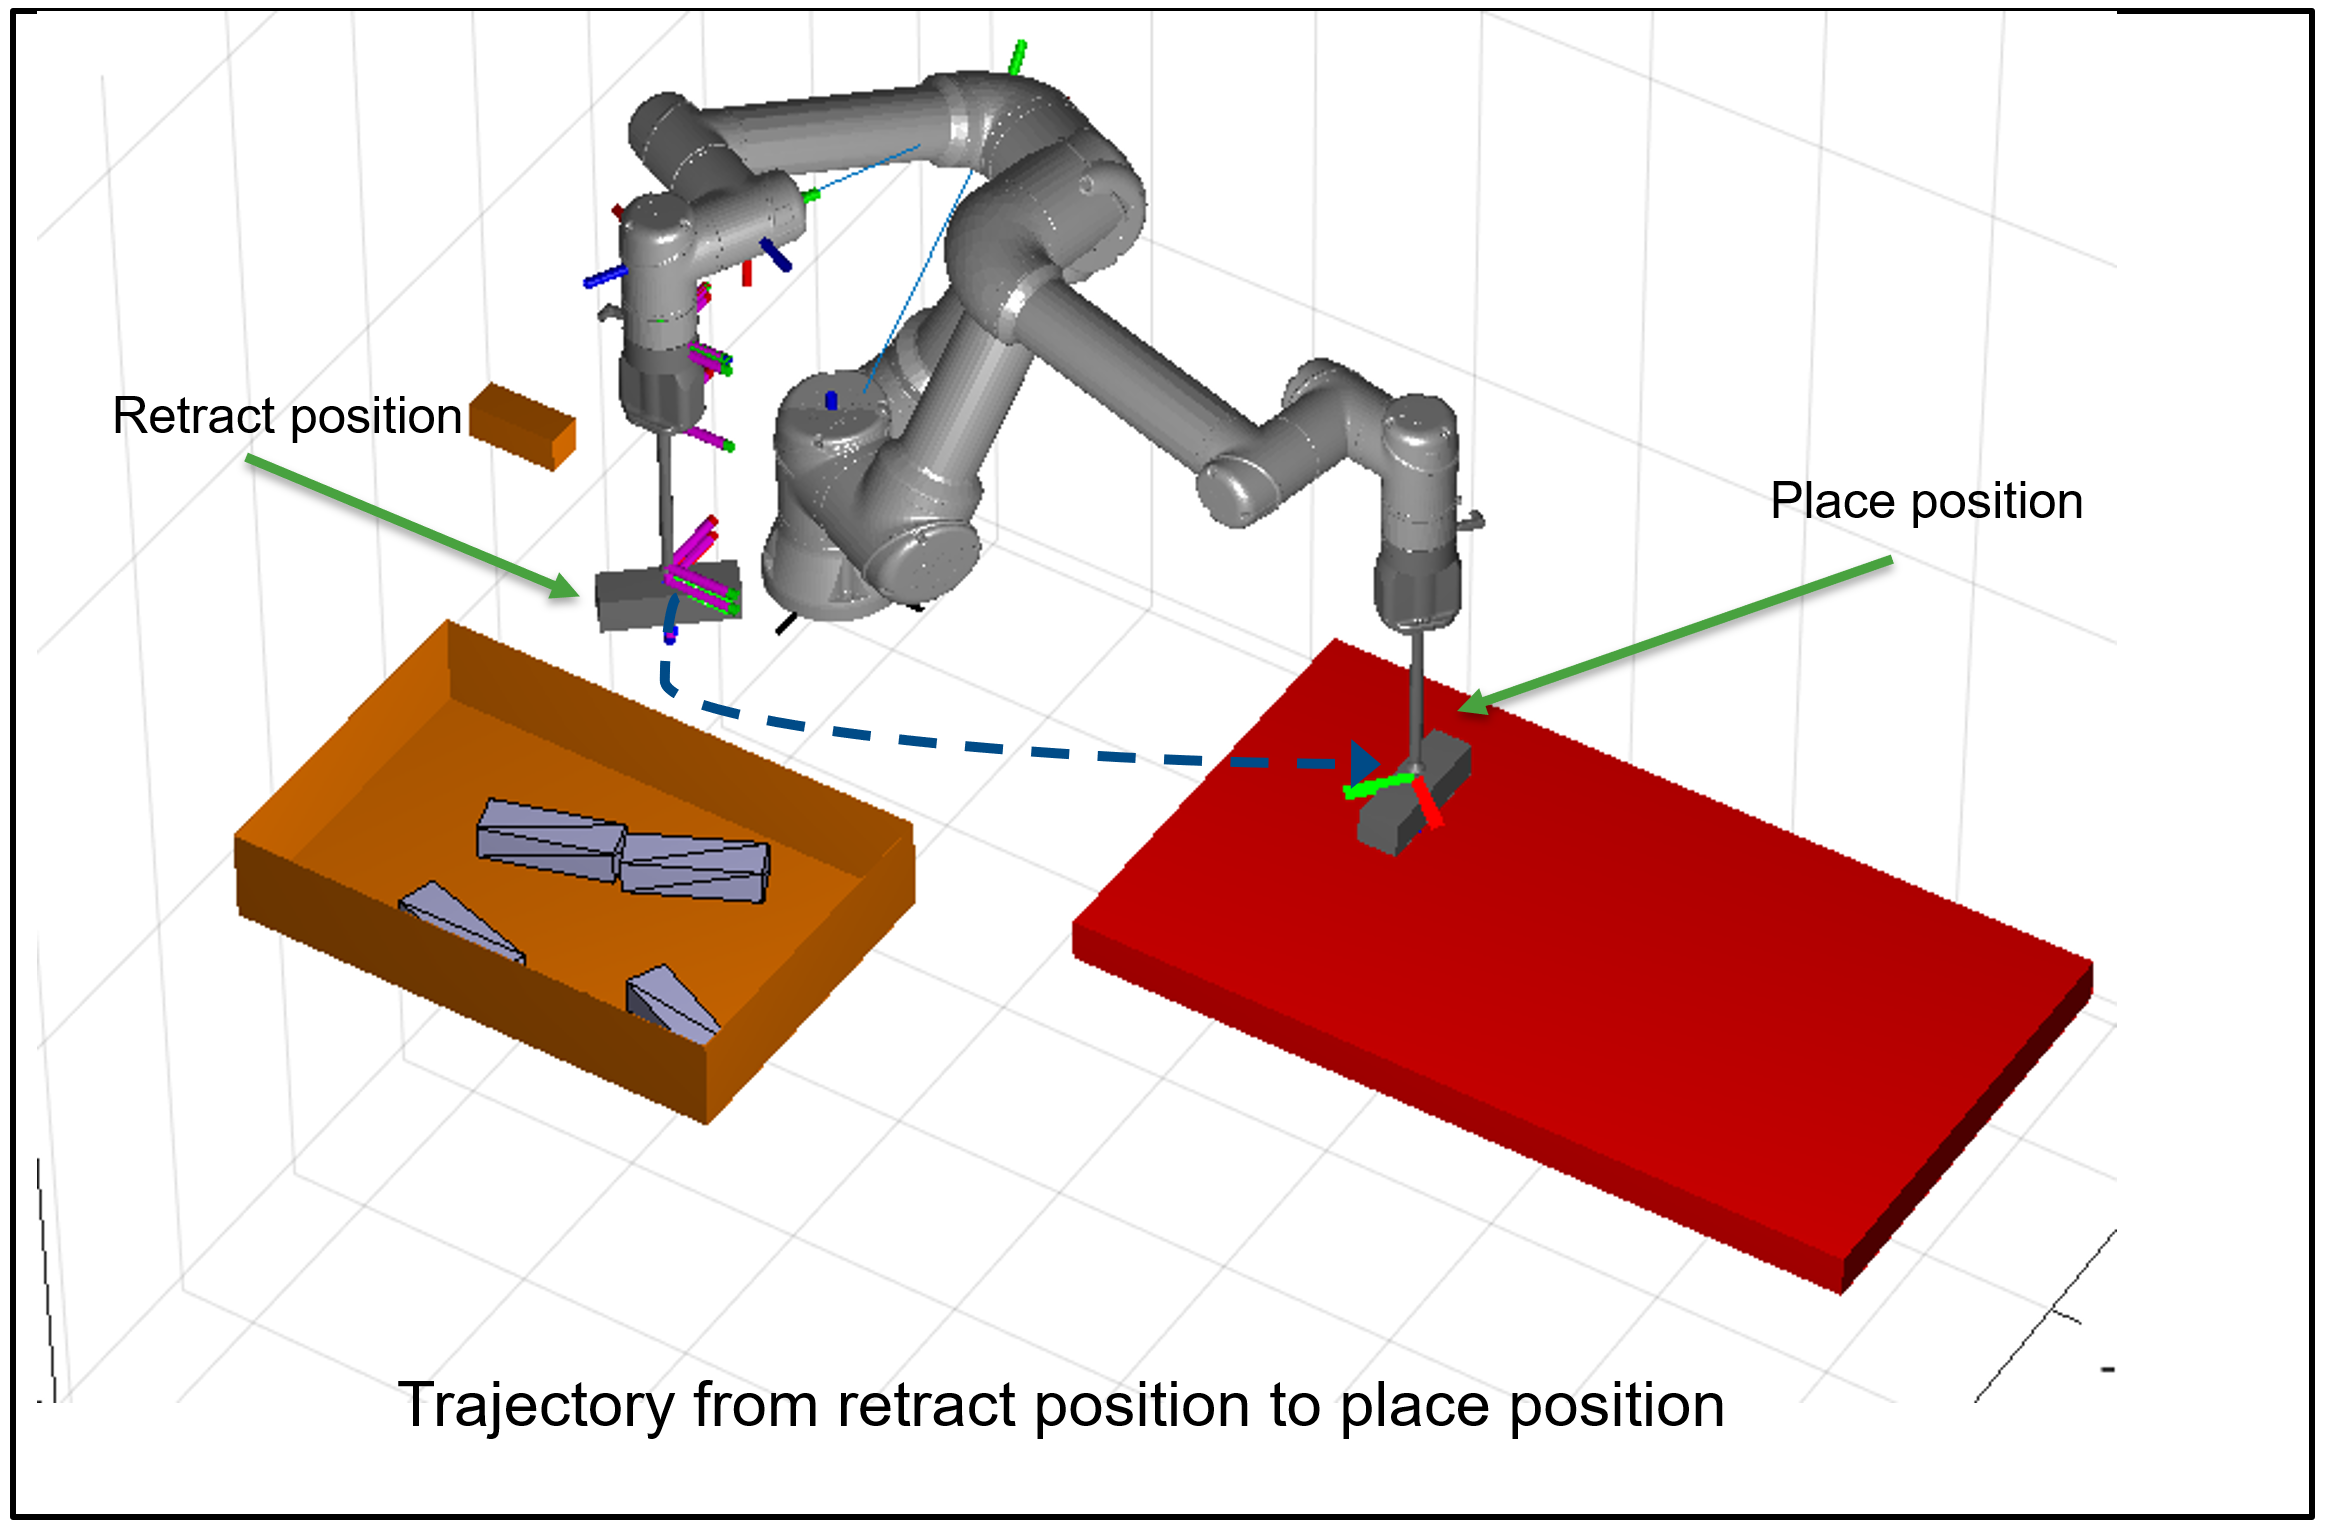

#### **Reset:**

Reset is defined as traversing from the last destination to the home position.

In this traversing phase, there is** no explicit trajectory computation**. For reset, `sendJointConfiguration `method is used with the pre-defined joint position. 

The rationale behind not using the trajectory here is to reduce the intermediate operation and hence the execution time.

The home position which is nothing but a reset position is chosen in such a way that the robot can freely traverse through the environment avoiding collision.

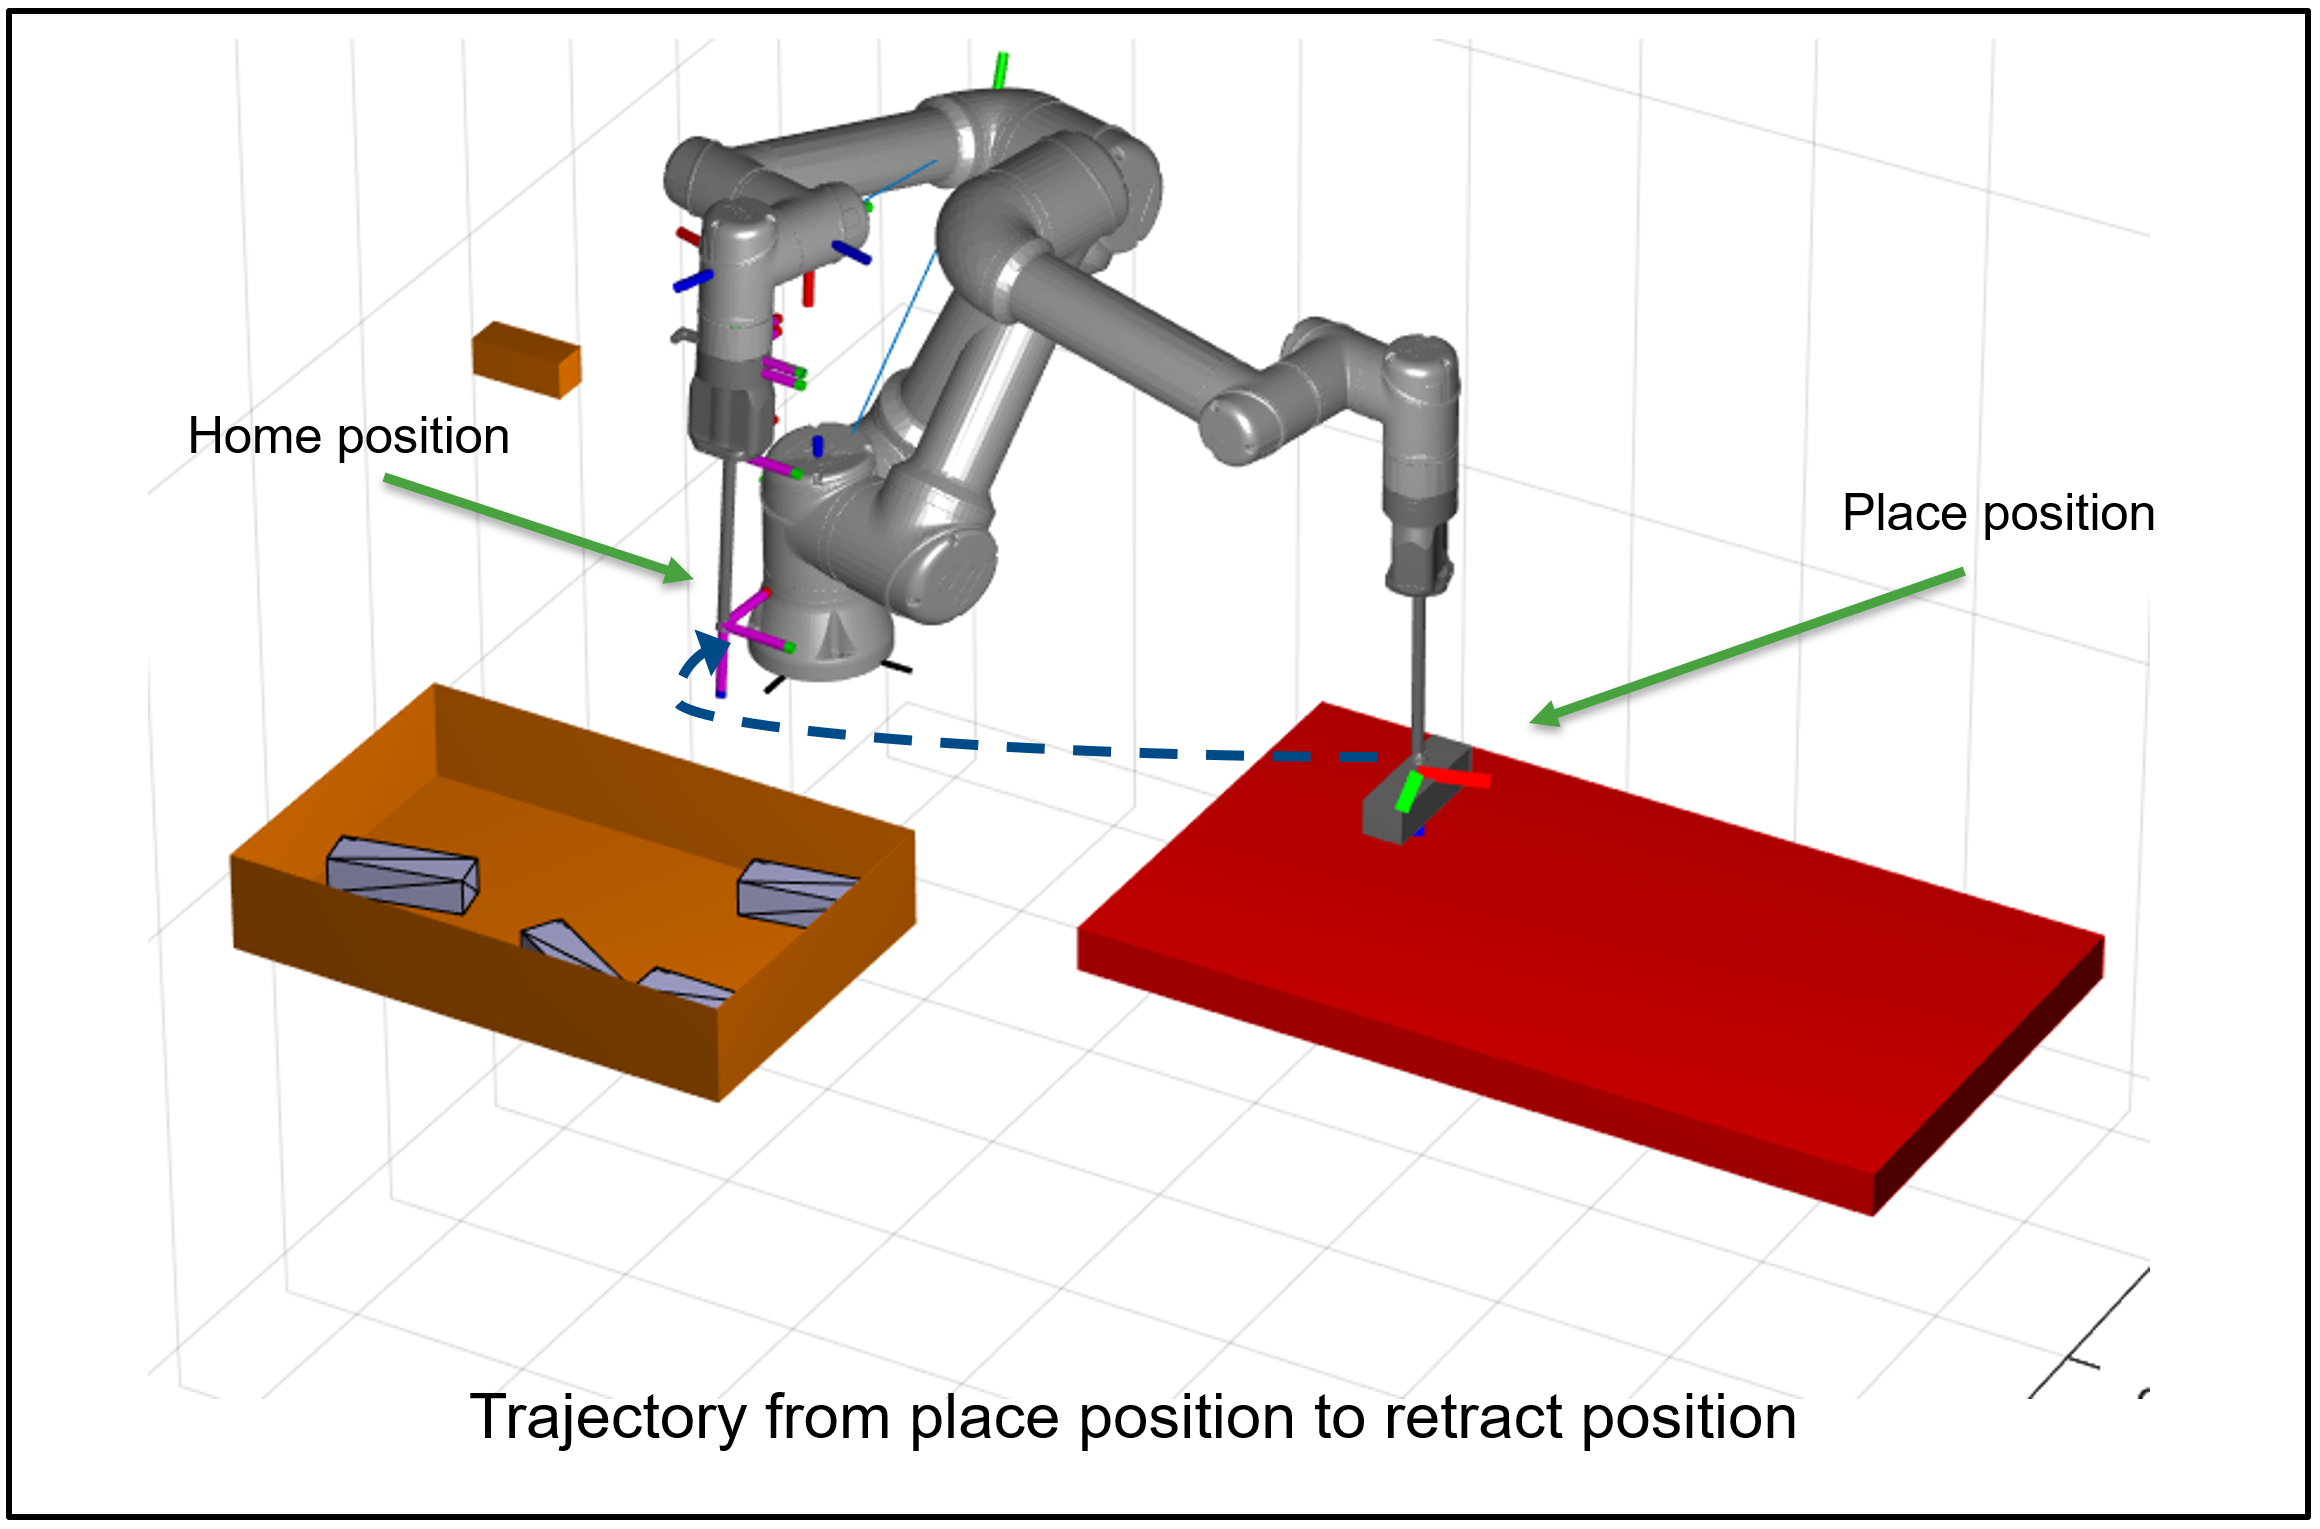

**Summary**

The final section of the planner used the interpolated plan to generate q, qd and qdd commands for the real world use case. The motion is divided into three sections.

The trajectories are generated using `contopptraj`, which provides constrained time-optimal trajectories. 

- Home to Pick - Trajectory Control

- Pick to Place - Trajectory Control

- Place to Home - Joint angle Control

The `Pick to Place` trajectory is generated by combining two separate plans. Due to this, the commanded end-effector velocity has a certain dip at the retract location. In the current implementation, this is handled by providing a normalized time allocation to `Pick to Retract` and `Retract to Place` based on the distance in joint space, and using this as the initial time guess to formulate a piecewise polynomial with spline interpolation. 

### Algorithm Flow Chart

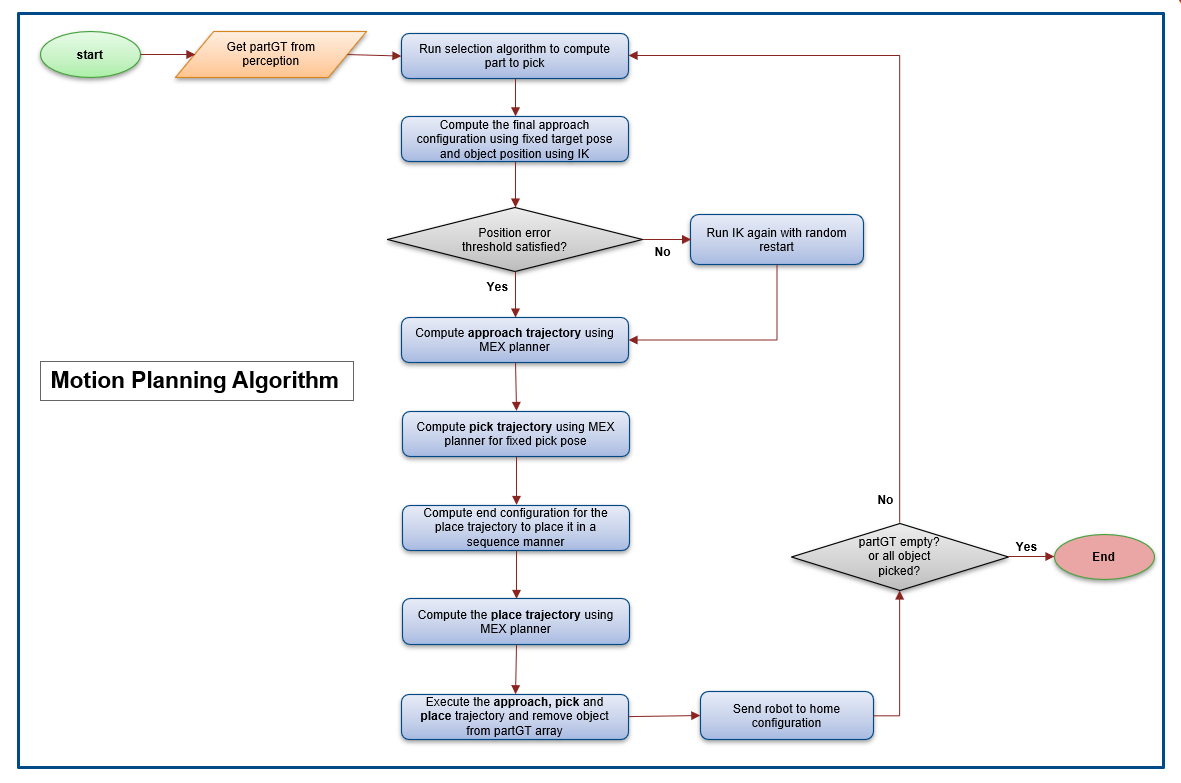

#### Choose planner function (MEX or without MEX as a standard function) 

Select a planner function to run in motion planning from the below drop-down menu. 

Choose "**MEX**" if you have generated a MEX function from the **Motion Planning** module earlier.

Choose "**Normal Execution**" if you have not generated a MEX function and you want to run the planner function as a standard MATLAB function execution.

Refer to the `BinPickingMotionPlanningMEXGenerationSim.mlx `to follow the steps for MEX function creation for this motion planner.

**Note**: It is recommended to generate and use the MEX function for the motion planning purpose as it accelerates the process by reducing the computation time for the pick and place cycle. 

plannerFunctionToRun = "MEX";

#### Trajectory computation and execution

Create `inverseKinematics `object for finding the end-configuration joints for motion planning.

ik = inverseKinematics('RigidBodyTree',ur5e);
ik.SolverParameters.AllowRandomRestart = false;
ik.SolverParameters.GradientTolerance = 1e-13;
ik.SolverParameters.MaxTime = 5;

% Set weight matrix
weights = [1 1 1 1 1 1];

Target pose angle for pick trajectory 

targetPoseAngleAtApproach = [0 pi 0];

Run a loop for the pick and place of each object.

for p = 1:numObjects
    disp("Starting computation for approach trajectory");
    %%%%%% Approach trajectory %%%%%%
    % Select part to pick basesd on selection algorithm
    [refPose,partID] = exampleHelperSelectPartForMEXPlanner(partGT,binCenterPosition);

    % Compute the target pose for the approach
    targetPoseXYZ = refPose;
    targetPose = trvec2tform(targetPoseXYZ)*eul2tform(targetPoseAngleAtApproach,"ZYX");

    % Compute final configuration for the approach using inverse kinematics
    initialGuess = homePosition;
    [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initialGuess);

    % Check that the computed final pose satisfies the position thresholds. If
    % the condition does not satisfied then compute IK with updated
    % paramters as shown below
    if solnInfo.PoseErrorNorm > poseThr
        ik.SolverParameters.MaxTime = 10;
        ik.SolverParameters.AllowRandomRestart = true;

        [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initialGuess);

        if solnInfo.PoseErrorNorm > poseThr
            warning("IK Failure");
            configSoln = [0.7950 -0.5093 0.2500 -1.3115 -1.5708 0];
        end
        planner.EnableConnectHeuristic = false;
    end

    % Set the start and end configuration and compute the path for the
    % approach using the RRT planner
    startConfig = homePosition;
    endConfig = configSoln;
    if plannerFunctionToRun == "MEX"
        [planPath,~,~] = exampleHelperBinPickingRRTMotionPlannerSim_mex(partID,partGT,startConfig,endConfig,'approach');
    else
        [planPath,~,~] = exampleHelperBinPickingRRTMotionPlannerSim(partID,partGT,startConfig,endConfig,'approach');
    end

    transformAtApptoach = getTransform(ur5e,planPath(end,:),ur5e.BodyNames{end});
    eulerAtApproach = tform2eul(transformAtApptoach);

    % Compute the interpolated trajectory using the computed path
    tpts=0:size(planPath,1)-1;
    pieceWisePolynomial1 = interp1(tpts,planPath,'pchip','pp');
    trajectorySampleTime1 = 1/400;
    [q_interp, qd_interp, qdd_interp, tSample] = exampleHelperTrajectoryInterpolation(pieceWisePolynomial1,trajectorySampleTime1,vellimits,accellimits);

    % Send approach trajectory to robot
    followTrajectory(ur,q_interp',qd_interp',qdd_interp',tSample);
    while ~ur.getMotionStatus
        pause(0.01);
    end


    %%%%%% Grab the object (Suction ON)%%%%%%
    activateVacuum();
    pause(0.5);

    %%%%%% Pick trajectory %%%%%%
    disp("Starting computation for pick trajectory")

    % Set the start and end configuration and compute the path for the
    % pick using the RRT planner
    startConfig = planPath(end,:);
    endConfig = [-0.4604   -2.0832    1.8080   -1.2956   -1.5708    1.1104];

    if plannerFunctionToRun == "MEX"
        [planPath1, shortPath1, ~]  = exampleHelperBinPickingRRTMotionPlannerSim_mex(partID,partGT,startConfig,endConfig,'place');
    else
        [planPath1, shortPath1, ~]  = exampleHelperBinPickingRRTMotionPlannerSim(partID,partGT,startConfig,endConfig,'place');

    end

    %%%%%% Place trajectory %%%%%%
    disp("Starting computation for place trajectory")

    % Set the start and end configuration and compute the path for the
    % place using the RRT planner
    startConfig = planPath1(end,:);

    targetPoseAngle = [-deg2rad(partGT(partID,4)) + eulerAtApproach(1) pi 0];
    if p>5
        targetPoseXYZ = [0.01+(p-6)*0.07 0.59 -0.018];
    else
        targetPoseXYZ = [0.01+(p-1)*0.07 0.75 -0.018];
    end
    targetPose = trvec2tform(targetPoseXYZ)*eul2tform(targetPoseAngle,"ZYX");

    initial_guess = [1.3792   -1.0821    1.2291   -1.7178   -1.5708    0];

    [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initial_guess);

    if solnInfo.PoseErrorNorm > poseThr
        ik.SolverParameters.MaxTime = 10;
        ik.SolverParameters.AllowRandomRestart = true;

        [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initial_guess);
    end

    endConfig = configSoln;

    if plannerFunctionToRun == "MEX"
        [planPath2, shortPath2, ~]  = exampleHelperBinPickingRRTMotionPlannerSim_mex(partID,partGT,startConfig,endConfig,'place');
    else
        [planPath2, shortPath2, ~]  = exampleHelperBinPickingRRTMotionPlannerSim(partID,partGT,startConfig,endConfig,'place');
    end

    % Combine pick and place path and interpolate
    path21 = planPath1;
    path22 = planPath2;

    % Normalised distance in joint space
    dist_joints_1 = norm(path21(1,:)-path21(end,:));
    dist_joints_2 = norm(path22(1,:)-path22(end,:));
    dist_total = dist_joints_1 + dist_joints_2;

    path2=[path21;path22];
    initialGuessPath2 = [linspace(0,dist_joints_1/dist_total,size(path21,1)) linspace(dist_joints_1/dist_total,1,size(path22,1))];

    % Remove Duplicate Rows
    path2(size(path21,1),:) = [];
    initialGuessPath2(size(path21,1)) = [];

    % Compute interpolated path for a combined path for pick and place
    pp = interp1(initialGuessPath2,path2,'pchip','pp');
    pieceWisePolynomial2 = interp1(initialGuessPath2,path2,'pchip','pp');
    trajectorySampleTime2 = 1/600;
    [q_interp, qd_interp, qdd_interp, tSample2] = exampleHelperTrajectoryInterpolation(pieceWisePolynomial2,trajectorySampleTime2,vellimits,accellimits);

    % Send pick+place trajectory
    followTrajectory(ur,q_interp',qd_interp',qdd_interp',tSample2);
    while ~ur.getMotionStatus
        pause(0.01);
    end


    %%%%%% Place the object (Suction OFF) %%%%%%
    deactivateVacuum();
    pause(0.5);

    % Delete picked part's ground truth
    partGT(partID,:) = [];

    %%%%%% Rest position %%%%%%
    % Send robot to home position after placing the object
    sendJointConfigurationAndWait(ur,homePosition,'EnDtime',1.5);
    pause(0.5);
end

Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


#### Kill ROS master

clear ur
system(device,'killall -9 rosmaster');